**Clear Functions**

clear;
close all;
clc;

**Define Vectors for "For Loop"**

r = zeros(4,1);
v = zeros(4,1);
vR = zeros(4,1);
hV = zeros(4,3);
h = zeros(4,1);
in = zeros(4,1);
NV = zeros(4,3);
K = [0,0,1;0,0,1;0,0,1;0,0,1];
N = zeros(4,1);
omegaRA = zeros(4,1);
eV = zeros(4,3);
e = zeros(4,1);
omega = zeros(4,1);
theta = zeros(4,1);
rp = zeros(4,1);
ra = zeros(4,1);
a = zeros(4,1);
T = zeros(4,1);

**Initial Conditions**

rE = 6378; % Radius of Earth (km)
mu = 3.986e5; %mu for Earth

% Inital position and velocity vectors

r0 = [-6045,-3490,2500; 
    4600,5359,2714; 
    6600,5259,2315;
    6000,4459,1914];
v0 = [-3.457,6.618,2.533;
    -5.532,3.218,4.532;
    -3.237,6.118,2.133;
    -3.532,0.5835,6.142];

**Calculating Orbital Elements**

for i = 1:4
   
    
    r(i) = norm(r0(i,:)); % Calc distance
    v(i) = norm(v0(i,:)); % Calc speed
    vR(i) = (dot(r0(i,:),v0(i,:)))/r(i); % Radial Velocity
    hV(i,:) = cross(r0(i,:),v0(i,:)); % Vector specific angular momentum
    h(i) = norm(hV(i,:)); % Magnitude of specific angular momentum
    in(i) = acosd((hV(i,3))/h(i)); % Inclination
   
    
    % Node line
    NV(i,:) = cross(K(i,:),hV(i,:)); % Node line vector
    N(i) = norm(NV(i,:)); % Magnitude of node line
    
    
    omegaRA(i) = acosd(NV(i,1)/N(i)); % Right Ascension (RA) of ascending node
    
    % Calculate eccentricity vector
    eV(i,:) = 1/mu*((v(i)^2-mu/r(i))*r0(i,:)-r(i)*vR(i)*v0(i,:));
    e(i) = norm(eV(i,:)); % Magnitude of eccentricity vector
    
    omega(i) = acosd(dot(NV(i,:),eV(i,:))/(N(i)*e(i))); % Argument of perigee
    
    theta(i) = acosd(dot(eV(i,:),r0(i,:))/(e(i)*r(i))); % True Anomaly
    
    rp(i) = (h(i)^2/mu)*(1/(1+e(i)*cosd(0))); % Perigee radii
    ra(i) = (h(i)^2/mu)*(1/(1+e(i)*cosd(180))); % apogee radii
    
    % 
    a(i) = 1/2*(rp(i)+ra(i)); % Semimajor axis (km)
    
    % a = (h^2/mu)/(1-e^2); % Semimajor axis (km)
    T(i) = 2*pi*(sqrt(a(i)^3/mu)); % Calculate period
     
end



**State Vector and Timespans**

s0 = [r0(1,:),v0(1,:);r0(2,:),v0(2,:);r0(3,:),v0(3,:);r0(4,:),v0(4,:);]; % First Orbit

timeSpan1 = 0:T(1);
timeSpan2 = 0:T(2);
timeSpan3 = 0:T(3);
timeSpan4 = 0:T(4);

**Call ODE45 Function**

*Note going to call multiple times for multiple orbits on same ECIF frame*

Inputs:* t, s, *$\mu$

Output: $\vec{\mathrm{sol}}$

[~, sol1] = ode45(@(t,s)diffEq(t,s,mu), timeSpan1, s0(1,:)); 
[~, sol2] = ode45(@(t,s)diffEq(t,s,mu), timeSpan2, s0(2,:)); 
[~, sol3] = ode45(@(t,s)diffEq(t,s,mu), timeSpan3, s0(3,:)); 
[~, sol4] = ode45(@(t,s)diffEq(t,s,mu), timeSpan4, s0(4,:)); 

**Figure Configuration**

figure;

hold on; grid on; grid minor; axis equal; rotate3d on
xlabel('X (km)')
ylabel('Y (km)')
zlabel('Z (km)')
title('Orbit')


[X, Y, Z] = sphere(); 

**Plotting Orbits and Earth**

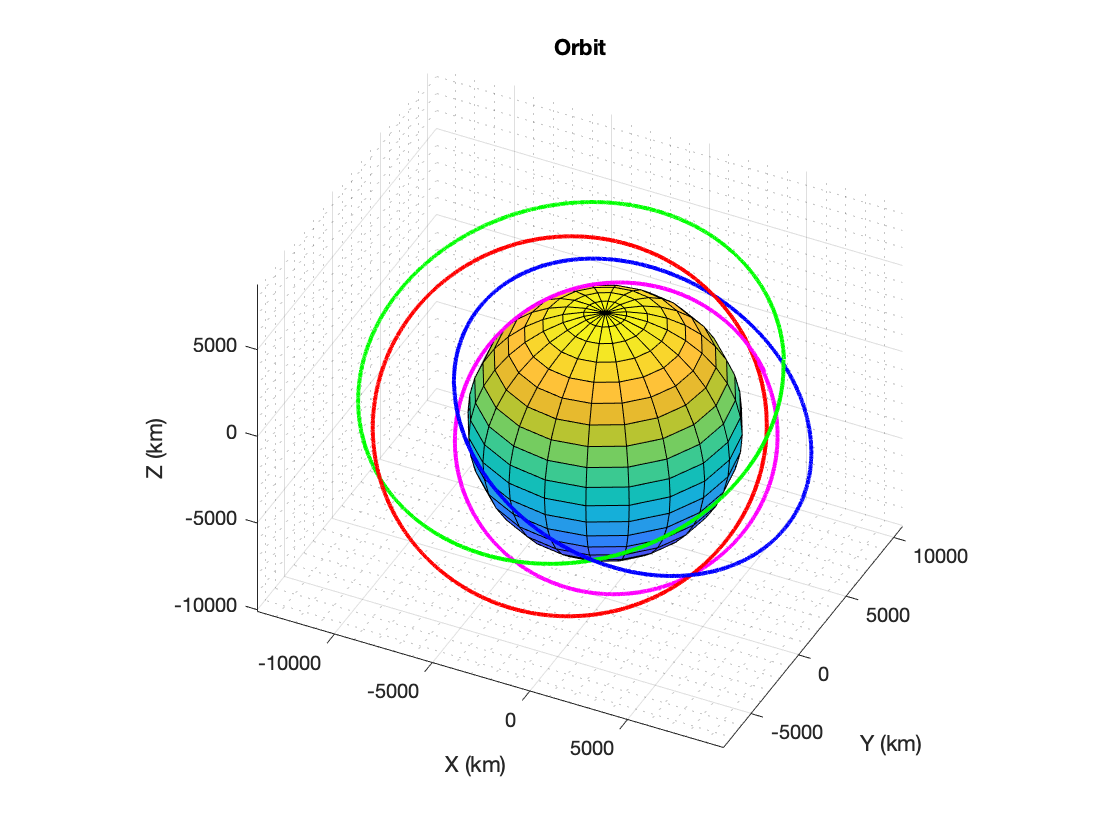

surf(X*rE, Y*rE, Z*rE)

plot3(sol1(:,1),sol1(:,2),sol1(:,3),'-b','LineWidth',2) 
plot3(sol2(:,1),sol2(:,2),sol2(:,3),'-r','LineWidth',2) 
plot3(sol3(:,1),sol3(:,2),sol3(:,3),'-g','LineWidth',2) 
plot3(sol4(:,1),sol4(:,2),sol4(:,3),'-m','LineWidth',2) 

view([26 37])

**Printing Outputs**

fprintf('\nGiven r = %.0fI + %.0fJ +%.0fK', r0(1), r0(2), r0(3));


Given r = -6045I + 4600J +6600K

fprintf('\nGiven v = %.0fI + %.0fJ +%.0fK', v0(1), v0(2), v0(3));


Given v = -3I + -6J +-3K

fprintf('\nEccentrcity: %.2f', e);


Eccentrcity: 0.17
Eccentrcity: 0.18
Eccentrcity: 0.29
Eccentrcity: 0.13

fprintf('\nPeriod = %.0f (sec)\n', T);


Period = 8199 (sec)

Period = 8620 (sec)

Period = 10426 (sec)

Period = 6533 (sec)


**ODE45 Function**

function sdot = diffEq(t,s,mu)

% r is first three elements, v is last three
rDQ = s(1:3);
vDQ = s(4:6);

sdot(1:3,1) = vDQ; %First three elements are velocity
sdot(4:6,1) = (-mu*rDQ)/(norm(rDQ))^3; % Actual two body EOM


end